#     Mechanics IX: Multivariable optimisation

**Name:** Ricardo Yépez

**Query**: Develop the corresponding algorithm for the multi-variable optimisation problem under the Box's evolution method for the example given in the lecture on 15 December, 2022

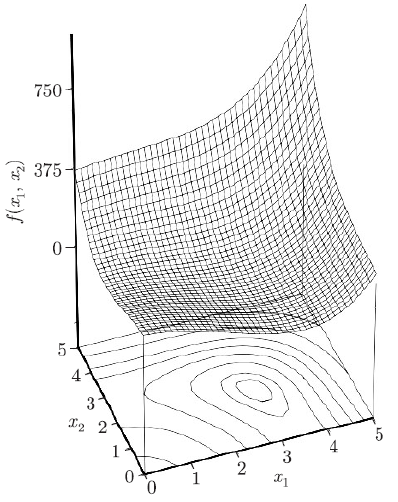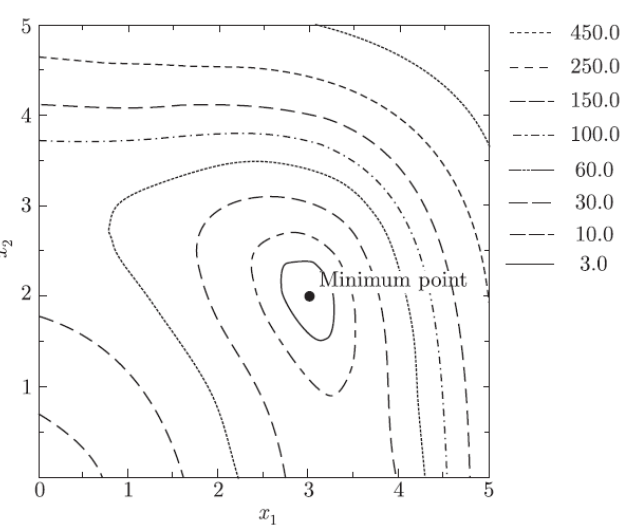

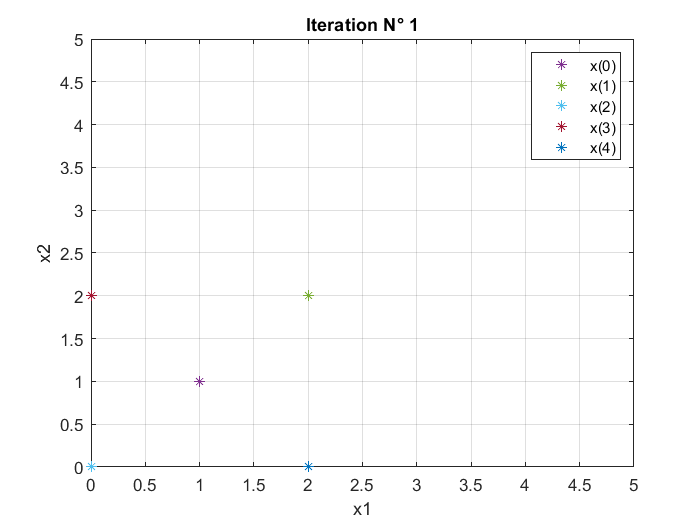

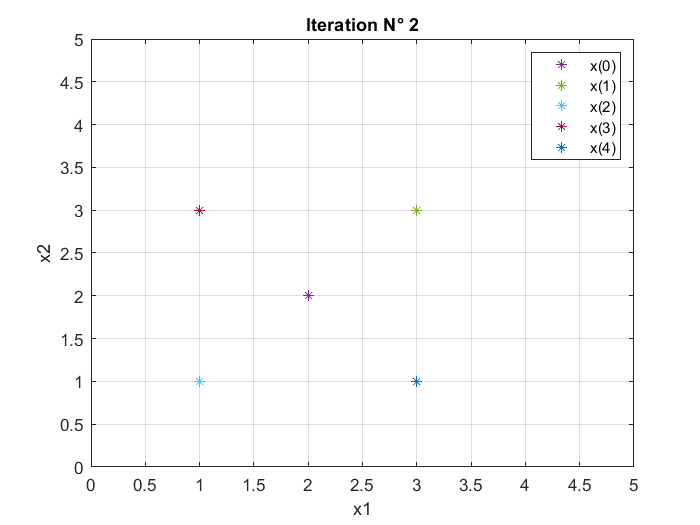

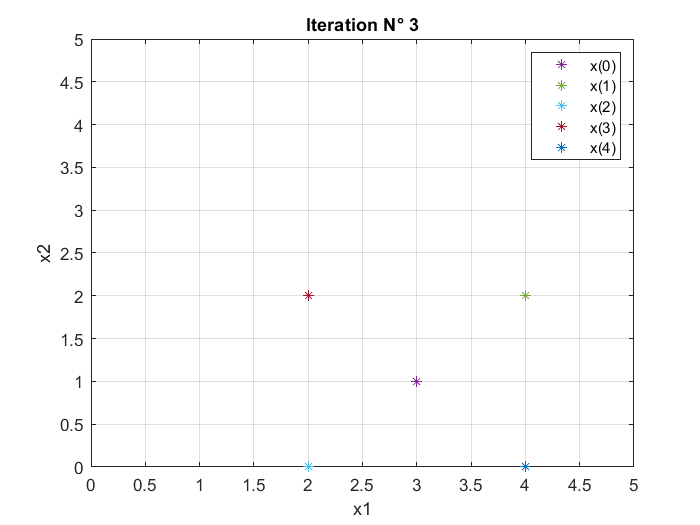

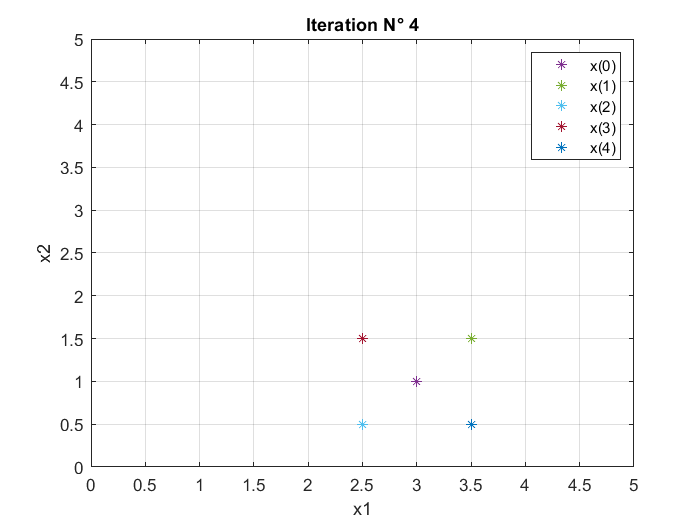

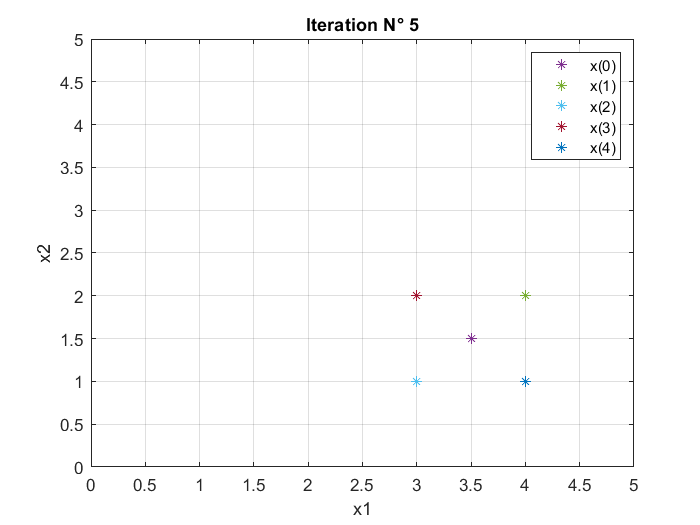

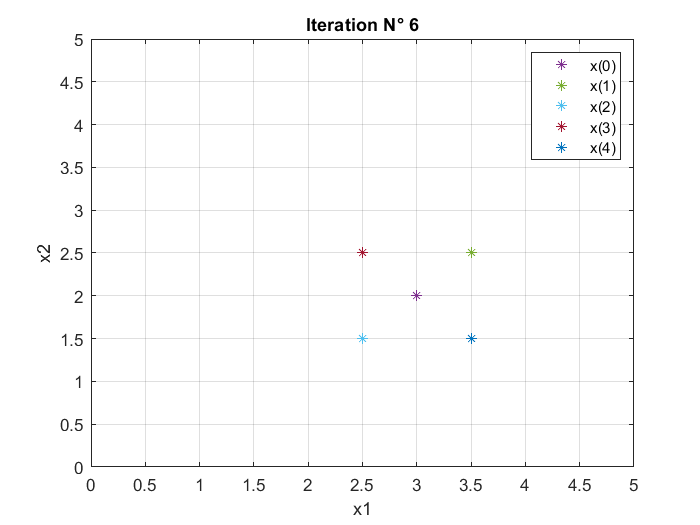


clc
clear all

%Conditions
n = 2;          %Number of variables
e = 1*10^-3;
points = 2^n;

x(:,1) = [1 1]';

%Step 1
delta = 2*x(:,1);

%Step 2
it = 1;
while(it<=100)
    s = delta/2;
    D_n = norm(delta);
    
    if D_n > e
        for i = 1:points
            if i == 1
                xi(:,i) = x(:,1) + s;
            end
            if i == 2
                xi(:,i) = x(:,1) - s;
            end
            if i == 3
                xi(:,i) = x(:,1) + [-s(1) s(2)]';
            end
            if i == 4
                xi(:,i) = x(:,1) + [s(1) -s(2)]';
            end
        end
        
    
        figure(it)
        p_x(1) = plot(x(1,1),x(2,1),'*');
        xlabel('x1')
        ylabel('x2')
        xlim([0 5])
        ylim([0 5])
        title(['Iteration N° ',num2str(it)])
        hold on 
        grid on
        
        for i = 1:points
            p_x(i+1) = plot(xi(1,i),xi(2,i),'*');
        end
        
        legend([p_x(1) p_x(2) p_x(3) p_x(4) p_x(5)],'x(0)','x(1)','x(2)','x(3)','x(4)')
        
        %Step 3
        fx(1) = f(x(1,1),x(2,1));
        fx1 = fx(1);
        for i = 1:points
            fx(i+1) = f(xi(1,i),xi(2,i));
        end
        
        [min_f d_f] = min(fx);
        
        xt(:,1) = x(:,1);
        for i = 1:points
            xt(:,i+1) = xi(:,i);
        end
      
        X_min = xt(:,d_f);
        
        %Step 4
        
        if X_min == x(:,1)
           delta = delta/2;
        else
           x(:,1) = X_min;
        end
        
        it = it + 1;
            
    else
        break
    end
    
end

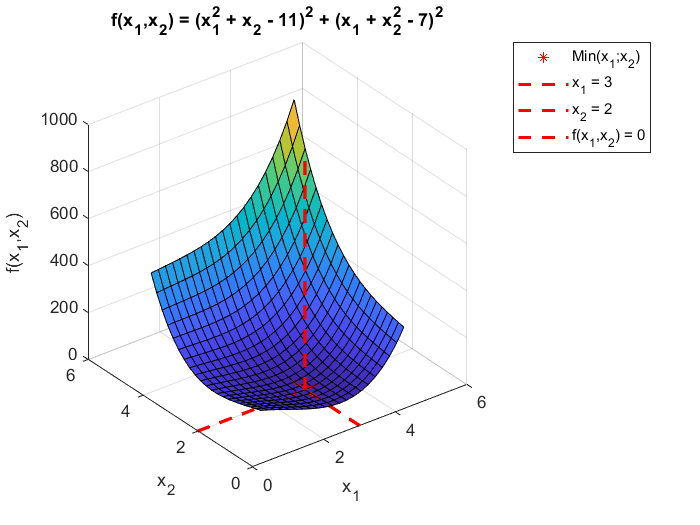


figure
[X1,X2] = meshgrid(1:.2:5);                                
f_x = (X1.^2 + X2 - 11).^2 + (X1 + X2.^2 - 7).^2;
surf(X1,X2,f_x)
title('f(x_1,x_2) = (x_1^2 + x_2 - 11)^2 + (x_1 + x_2^2 - 7)^2')
xlabel('x_1')
ylabel('x_2')
zlabel('f(x_1,x_2)')
hold on

po = plot3(X_min(1),X_min(2),min_f,'*','color','r');

xl = line([0,5],[X_min(2),X_min(2)],[0,0],'Color', 'r','LineStyle','--', 'LineWidth', 2);
yl = line([X_min(1),X_min(1)],[0,5],[0,0],'Color', 'r','LineStyle','--', 'LineWidth', 2);
zl = line([X_min(1),X_min(1)],[X_min(2),X_min(2)],[0,1000],'Color', 'r','LineStyle','--', 'LineWidth', 2);

legend([po xl yl zl],'Min(x_1;x_2)','x_1 = 3','x_2 = 2','f(x_1,x_2) = 0')

fprintf('Minimum point X1, X2: [%d;%d]',X_min(1),X_min(2))

Minimum point X1, X2: [3;2]

fprintf('Number of Iterations: %d',it)

Number of Iterations: 17

function funcion = f( x1 , x2 )
    funcion = (x1.^2 + x2 - 11).^2 + (x1 + x2.^2 - 7).^2;   
end